# Rectifiers

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

Power electronics play a major role in everyday life, such as converting the electricity between a power source and its load. Rectifiers are a type of power electronic that convert alternating current (AC) to direct current (DC). This conversion process is known as rectification. Without rectification, you could damage the device you are trying to charge/use or the device may not charge at all. Let's take a smartphone charger for example. The power coming from the plug in the wall is AC, and the charger is a rectifier that converts that AC to DC in order to charge a smartphone safely. If there were no rectifier in this setup, the phone would receive direct AC power and not charge. This is because the battery would charge during the positive cycle of the AC signal and then discharge on the negative cycle. Concepts like this can also be applied to the effective and safe charging of electric vehicles. In this script, we will explore the theory and applications of rectifiers in power electronics.

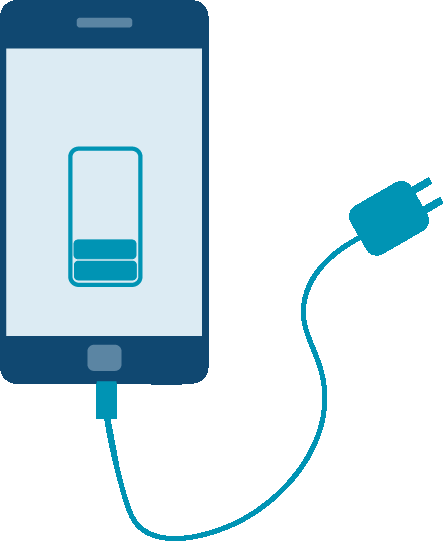

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB Toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://www.mathworks.com/learn/tutorials/matlab-onramp.html), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if they run out of order.

## Types of rectifiers

The majority of the everyday portable devices we use operate on DC power. Because of this, we need to use rectifiers in places like our households so that we can convert the AC power coming out of the wall to something more useful for our personal devices. There are two main classifications of rectifiers: uncontrolled and controlled [1]. Both of these types of rectifiers are described in the Rectifier Classification table below:

A further breakdown of these types of rectifiers are half-wave and full-wave rectifiers. Both uncontrolled and controlled rectifiers can have both half-wave and full-wave types as needed for the particular application. The Rectifier Type table provides a visualization for the different types. We will cover them in more detail in a later section. 

  **Try**. Use the drop down menu below to view the different types of rectifiers.

switchRectifier("No Selection");

 **Exercise 1. **Which of the following choices are considered to be real applications of rectifiers? Please select all that apply and click the **Submit Answers** button below.  

exerciseSol1(...
    A = false, ...
    B = false, ...
    C = false, ...
    D = false);

### Half-wave rectifier 

Half-wave rectifiers are generally used in low-power applications because their voltage output is not uniform by design. A half-wave means that half of the AC power is lost before being converted. Another way to look at this is this type of rectifier only converts the positive cycle of the AC signal into a DC signal. 

** Demonstration**. Let's simulate a simple half-wave rectifier to visualize the behavior of the circuit.

% View half-wave signal
hwFlag = false;

% Run the Simscape model for the half-wave rectifier and store data from
% simulation
if hwFlag
    HWRectData = sim("Models/HalfWaveRectifier.slx","StopTime","0.1"); %#ok<UNRCH>

    % Plot half-wave rectifier output voltage signal
    t1 = HWRectData.ScopeData1(:,1);
    v1 = HWRectData.ScopeData1(:,2);
    t2 = HWRectData.ScopeData(:,1);
    v2 = HWRectData.ScopeData(:,2);
    plot(t1,v1,':',t2,v2,'-','LineWidth',2);
    xlabel('Time (sec)'); ylabel('DC Voltage (V)');
    title('Half-Wave Rectifier Output Voltage');
    legend("Original Signal","Rectified Signal");
end

  **Try**. Explore an **uncontrolled half-wave rectifier** in Simscape that created the half-wave signal. Notice that the half-wave rectifier only has one diode in its circuit. This is because only half of the cycle (positive) is converted. You can simulate the model using the run icon  .

 

% Open Simscape model for the half-wave rectifier 
open_system("Models/HalfWaveRectifier.slx")

### Full-wave rectifier

A full-wave rectifier converts both the positive and negative cycles of the AC signal into a DC voltage signal, utilizing all of the available power being provided. The two common types of full-wave rectifiers are the center-tapped and bridge rectifiers. The difference between the two is the center-tapped rectifier requires a transformer and the bridge rectifier has twice as many diodes as the center-tapped rectifier. Bridge rectifiers are more commonly used because they are lightweight, have good efficiency in power conversion, and the cost of diodes is low. We won't be covering center-tapped rectifiers in this module, but you can interact with a model that simulates one: [Open Center-Tapped Rectifier Model](matlab:open('..\Models\FullWaveRectifierCT.slx')). 

** Demonstration**. Let's simulate a simple full-wave rectifier to visualize the behavior of the circuit.

% View full-wave signal
fwFlag = false;

% Run the Simscape model for the full-wave rectifier and store data from
% simulation
if fwFlag
    FWRectData = sim("Models/FullWaveBridgeRectifier.slx","StopTime","0.1"); %#ok<UNRCH>

    % Plot half-wave rectifier output voltage signal
    t3 = FWRectData.ScopeData1(:,1);
    v3 = FWRectData.ScopeData1(:,2);
    t4 = FWRectData.ScopeData(:,1);
    v4 = FWRectData.ScopeData(:,2);
    plot(t3,v3,':',t4,v4,'-','LineWidth',2);
    xlabel('Time (sec)'); ylabel('DC Voltage (V)');
    title('Full-Wave Bridge Rectifier Output Voltage');
    legend("Original Signal","Rectified Signal");
end

  **Try**. Explore an **uncontrolled full-wave bridge rectifier** in Simscape that created the full-wave signal. Notice that the full-wave bridge rectifier has four diodes in its circuit. This is to create a "bridge" that allows two diodes to conduct current during the positive cycle and the other two to conduct current during the negative cycle, converting the full power of the AC to DC.

 

% Open Simscape model for the full-wave rectifier 
open_system("Models/FullWaveBridgeRectifier.slx")          

 **Reflect. **Observe the diodes within the previous models had a forward voltage and resistance that were both non-zero values. An ideal diode is defined by having both of these parameters set to zero. Therefore, the diodes within the models are characterized as real.

### Uncontrolled vs. Controlled rectifiers

The goal of rectification is to convert from AC power to DC power. We have explored uncontrolled rectifiers for low-power applications like cell phone or laptop batteries. What if we wanted to manage the voltage and current going towards a particular load? This is where a controlled rectifier would come into play. Some examples of where a controlled rectifier would be useful are in high-power applications such as locomotives, electric cars, and airplanes. You will observe that the controlled rectifier circuit is structured similarly to the uncontrolled rectifier circuit. The primary difference is that controlled rectifiers will have a thyristor in place of a diode for converting the AC power to DC power. Thyristors are more reliable than regular diodes because they can control the flow of current, withstand high power and temperature, and have a much faster response time to changes in voltage. By adjusting the firing angle in the thyristors, the voltage and current can be managed to the specifications that need to be met for the system [2]. 

### Simulating rectification in a smartphone battery

In this next example, we will explore a **controlled full-wave bridge rectifier** with a typical smartphone battery as the application. Imagine you own a smartphone and you are charging it using a standard outlet in your home. Using a controlled rectifier, we want to manage the input to the battery at 5VDC. The firing angle for the thyristors has been automatically set in the following model for your convenience.

 **Exercise 2. **Launch the model using the button below. In the open model, you will see a few [subsystems](https://www.mathworks.com/help/simulink/subsystems.html) containing various components. Which subsystem contains the rectifier? Please select an option from the drop-down menu and click the **Submit Answers** button below. 

 

% Open Simscape model for the smartphone battery rectifier
open_system("Models/SmartphoneBatteryRectifierModel.slx")

exerciseSol2("No Selection")

 **Exercise 3. **Begin by simulating the open model. Using the [scope](https://www.mathworks.com/help/simulink/slref/scope.html) block labeled as "Results", what is the total power (in Watts) that is being consumed in the charging of the smartphone battery?

 

% Simulate Simscape model for the smartphone battery rectifier
set_param('SmartphoneBatteryRectifierModel',"StopTime","0.1");
sim("Models/SmartphoneBatteryRectifierModel.slx","StopTime","0.1");
disp("The total simulation time elapsed for exercise 3 is 0.1 seconds.")

 **Note.** Recall that power is calculated by the following equation: $P = V * I$, where V is the voltage and I is the current. 

Analyze the first two plots labeled as "Current" and "Voltage" in the scope. Use the zoom Y tool   in the scope toolstrip to **estimate** the peak values for voltage and current. If the plot is not scaled upon opening the scope, use the Scale X and Y Axes Limits tool  .

power = 0;
exerciseSol3(power);

 **Exercise 4. **Simulate the open model again. Using the scope block labeled "Results", determine the amount of time (in hours) that it will take to fully charge (100%) the smartphone battery from its current state of charge, 25%.

 

% Simulate Simscape model for the smartphone battery rectifier
set_param('SmartphoneBatteryRectifierModel',"StopTime","10");
sim("Models/SmartphoneBatteryRectifierModel.slx","StopTime","10");
disp("The total simulation time elapsed for exercise 4 is 10 seconds.")

 **Note.** Analyze the third plot labeled as "Charge" in the scope. This details the percent of charge in the battery as it increases over time. The simulation ran for 10 seconds going from 25% to ~25.443% charge. You can use this data to extrapolate to 100% charge. This can be achieved by finding the slope of the Charge % straight line. Recall the slope formula as: $slope = m = \frac{(y_2 - y_1)}{(x_2 - x_1)}$ and the slope-intercept form as: $y = mx+ b$, where b = 25. b is set to 25 because it is the first point to intercept the y-axis (25%) on the Charge % plot.

Open the scope block. Use the Scale X and Y Axes Limits tool   in the toolstrip to make the charge signal easier to see. Select the cursor measurements tool   to find the values for your slope calculation. Before finding the values, make sure to select "Charge %" in the "Trace Selection" drop-down menu. Under "Cursor Measurements", set the time values to 1 and 10 in the edit fields, respectively. Use the zoom Y   tool to **estimate** the Charge % slope. **Do not round your final answer.**

Once you have a value for the slope (**units in %/seconds**), use the slider below to calculate your slope-intercept form (*where you want y to be as close to 100% as possible*) with x as the value on the slider (**in seconds**).

slope = 0; % Charge/time (sec)
exerciseSol4(slope);

t =0; % Seconds
b = 25;
charge = (slope*t) + b;
disp(['The Smartphone battery will be ' num2str(round(charge,2)) '% charged in ' num2str(round(t/3600,2)) ' hours.'])

time = 0;
exerciseSol5(time);

 **Note. **Open the scope and look at the "Cursor Measurements" section for the Charge %. You may notice that there is a value in that window expressed as $\Delta Y/\Delta T$. Compare the slope that you calculated to the value in the scope. How close were you to the exact value? 

 **Note.** The scope block is used to display specific parameters chosen by the user. What if you want to view **all** of the parameters across blocks in a model? The Simulink Data Inspector   tool allows you to view all of your parameters in one place. Once a simulation is run, a `simlog `variable will appear in the workspace. Click the data inspector icon and select the import data button . Select the import button, and you will be able to view all the signals and parameters in the model.

 **Reflect.** How good is the extrapolation that was performed? Was the charge fast or slow? What feature of the rectifier could you change that would improve the charging performance and, thus, the extrapolation?

## Next Steps

This script covered the fundamentals of rectifiers in power electronics, specifically uncontrolled and controlled rectifiers. In later sections of this power electronics module, we will explore other related topics on inverters and converters.

## Glossary

Diode -  A semiconductor device that behaves like a one-way valve, allowing current to only flow in one direction. (↑ Return to Text)

Thyristor - A four-layered semiconductor device in which the flow of current between two electrodes is controlled by an input signal at a third electrode. These are more commonly known as a Silicon Controlled Rectifier (SCR) or Metal-Oxide-Semiconductor Field-Effect Transistor (MOSFET). (↑ Return to Text)

Firing Angle - The angle in the AC cycle at which the thyristor starts conducting. Ex. If the firing angle is 45 degrees, then the thyristor will begin conducting when the phase angle is 45 degrees, until the cycle completes. It will then repeat as the AC cycle continues. (↑ Return to Text)

## Further Exploration

- [Power Electronics Simulation in MATLAB](https://www.mathworks.com/solutions/electrification/power-electronics-simulation.html)

- [Power Electronics Simulation Onramp](https://matlabacademy.mathworks.com/details/power-electronics-simulation-onramp/powerelectronics)

- [MathWorks Examples: Power Converters](https://www.mathworks.com/help/sps/examples.html?category=power-converters&s_tid=CRUX_topnav)

- [MathWorks: Introduction to Diode Rectifiers](https://www.mathworks.com/videos/what-is-3-phase-power-part-5-introduction-to-diode-rectifiers-1655099875869.html)

- [MathWorks Example: Uncontrolled Full-Wave Bridge Rectifier](https://www.mathworks.com/help/simscape/ug/full-wave-bridge-rectifier.html)

- [Power Electronics with Speedgoat for RCP & HIL](https://www.speedgoat.com/solutions/industries/power-electronics?utm_term=power%20electronics%20matlab&utm_source=google&utm_medium=cpc&device=c&utm_campaign=10278398312&utm_adgroup=135515401899&utm_content=591792460255&gad_source=1&gclid=EAIaIQobChMIy5nB66CEhAMVXl9HAR2KgQSMEAAYASAAEgK42_D_BwE)

## References

[1] Electrical Technology (n.d.). *Types of Rectifiers*. Www.Electricaltechnology.org. Retrieved January 29, 2024, from [https://www.electricaltechnology.org/2019/01/what-is-rectifier-types-of-rectifiers-their-operation.html](https://www.electricaltechnology.org/2019/01/what-is-rectifier-types-of-rectifiers-their-operation.html) (↑ Return to Text)

[2] Monolithic Power Systems (n.d.). *Controlled Rectifiers*. Www.Monolithicpower.com. Retrieved January 29, 2024, from [https://www.monolithicpower.com/en/power-electronics/ac-dc-converters/controlled-rectifiers](https://www.monolithicpower.com/en/power-electronics/ac-dc-converters/controlled-rectifiers) (↑ Return to Text)

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

## Local Helper Functions

If you want to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

function switchRectifier(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["No Selection" "Half-Wave Rectifier" "Full-Wave Center-Tapped Rectifier" "Full-Wave Bridge Rectifier"])}
end

if opt == "No Selection"
else
    if opt == "Half-Wave Rectifier"
        rect = imread("Images/HWRectifier.png");
        imshow(rect,Interpolation="bilinear");
    elseif opt == "Full-Wave Center-Tapped Rectifier"
        rect = imread("Images/FWCenterTap.png");
        imshow(rect,Interpolation="bilinear");
    elseif opt == "Full-Wave Bridge Rectifier"
        rect = imread("Images/FWBridge.png");
        imshow(rect,Interpolation="bilinear");
    end
end
end

function exerciseSol1(opts)
    % Provides solution for Exercise 1
    arguments
        opts.A (1,1) logical
        opts.B (1,1) logical
        opts.C (1,1) logical
        opts.D (1,1) logical
    end

    if ~any([opts.A opts.B opts.C opts.D])
        disp("Please select all that apply!")
    elseif [opts.A opts.C opts.D] & ~opts.B %#ok<AND2,BDSCA>
        disp("Correct! These are all examples of rectifiers.")
    elseif [opts.A opts.C] & ~[opts.B opts.D] | [opts.A opts.D] & ~[opts.B opts.C] | [opts.C opts.D] & ~[opts.A opts.B] %#ok<AND2,OR2,BDSCA>
        warning("Incorrect. You have not selected all applications of rectifiers.")
    elseif opts.A
        warning("Part of an automobiles' charging system is alternator which produces AC current. The battery in the car is DC. Rectification takes place between the alternator that charges and the battery that stores. However, this is not the only example of a rectifier.")
    elseif opts.B
        warning("Solar panel systems turn solar power into DC power. And an inverter is used to go from DC to AC. There is not a rectifier in the conversion process.")
    elseif opts.C
        warning("Smartphone and laptop chargers are very common examples of components that must perform rectification. However, this is not the only example of a rectifier.")
    elseif opts.D
        warning("Flat screen TVs take in AC power from the wall. The internal components run on DC power and therefore must have rectfication performed internally. However, this is not the only example of a rectifier.")
    end
end

function exerciseSol2(subs)
    % Provides solution for Exercise 2
    arguments
        subs (1,1) string {mustBeMember(subs,["No Selection" "Wall Outlet AC Power" "Smartphone Charger" "Smartphone" "Results"])} = "No Selection"
    end

    switch (subs)
        case "No Selection"
            disp("Please select one of the options in the drop down menu.")
        case "Wall Outlet AC Power"
            warning("This is a subsystem that contains the AC Power coming from the wall outlet. This what would be considered the source in the system, which is upstream of the rectifier.")
        case "Smartphone Charger"
            disp("Correct! The Smartphone Charger, will contain your transformer to step down the voltage and the rectifier that converts the AC power to DC power.")
        case "Smartphone"
            warning("This is a subsystem that contains the Smartphone battery. This is what would be considered the load in the system, which is downstream of the rectifier.")
        case "Results"
            warning("This is NOT a subsystem block. This is a scope block which allows you to visualize the data in your simulation.")
    end
end

function exerciseSol3(power)
    % Provides solution for Exercise 3
    arguments
        power (1,1) double
    end

    errMargin = 1; % Watts
    if power >= (326 - errMargin) && power <= (326 + errMargin)
        disp("Correct! You have properly calculated the total power consumed.")
    elseif power == 0
        disp("Please enter your answer.")
    else
        warning("Your answer has exceeded the tolerance of the possible solutions. Please measure the peaks of the signals and try again.")
    end
end

function exerciseSol4(slope)
    % Provides solution for Exercise 4 pt 1
    arguments
        slope (1,1) double
    end

    slopeMargin = 0.0002; % Change in Charge/Change in Time
    if slope >= (0.0440 - slopeMargin) && slope <= (0.0442 + slopeMargin)
        disp("Correct! You have properly calculated the slope of the Charge % line.")
    elseif slope == 0
        disp("Please enter your answer.")
    else
        warning("Your answer has exceeded the tolerance of the possible solutions. Please measure the slope of the signal again.")
    end
end

function exerciseSol5(time)
    % Provides solution for Exercise 4 pt 2
    arguments
        time  (1,1) double
    end

    timeMargin = 0.1; % Seconds
    if time >= (0.47 - timeMargin) && time <= (0.47 + timeMargin)
        disp("Correct! You have properly determined the time it will take to charge the Smartphone battery to 100%.")
    elseif time == 0
        disp("Please enter your answer.")
    else
        warning("Your answer has exceeded the tolerance of the possible solutions. Please check the slider to verify that the battery is charged to 100%.")
    end
end